# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.6 特殊绘图

#### 2.6.11 在随机圆里产生随机点

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

画圆用极坐标方式，没有问题

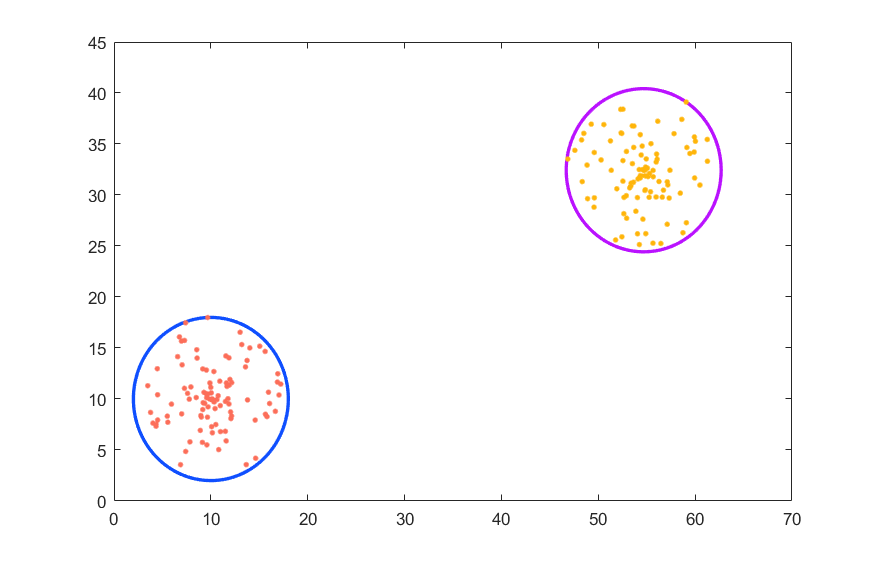

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors(); 
% 半径
r = 8;
% 圆心距
d = 50;
% 圆 1 的坐标，可变
ox1 = 10;
oy1 = 10;
% 圆 2 的坐标，可变，那就随机吧
theta_r = rand*2*pi;
ox2 = ox1 + d*cos(theta_r);
oy2 = oy1 + d*sin(theta_r);
% 用极坐标形式，毫无疑问
theta = linspace(0, 2*pi, 100);
% 圆坐标
x1 = ox1 + r*cos(theta);
y1 = oy1 + r*sin(theta);
x2 = ox2 + r*cos(theta);
y2 = oy2 + r*sin(theta);
% 画图
plot(x1, y1, 'Color', all_colors(19, :), 'LineWidth', 2);
hold on
plot(x2, y2, 'Color', all_colors(24, :), 'LineWidth', 2);
count = 100;
% 散点位置
% 随机半径
rs1 = rand(1, count)*r;
% 随机角度
thetas1 = rand(1, count)*2*pi;
% 确定坐标
xs1 = ox1 + rs1 .* cos(thetas1);
ys1 = oy1 + rs1 .* sin(thetas1);
% 同样来一遍
rs2 = rand(1, count)*r;
thetas2 = rand(1, count)*2*pi;
xs2 = ox2 + rs1 .* cos(thetas2);
ys2 = oy2 + rs1 .* sin(thetas2);
% 画图
plot(xs1, ys1, '.', 'Color', all_colors(1, :), 'MarkerSize', 10);
plot(xs2, ys2, '.', 'Color', all_colors(2, :), 'MarkerSize', 10);
hold off
% 设置一下显示比例
x_range = xlim;
y_range = ylim;
x_len = x_range(2) - x_range(1);
y_len = y_range(2) - y_range(1);
set(gcf, 'Position', [50, 50, x_len*10, y_len*10]);